# Plot and Solve a System of Linear Equations

## Task 1

In this activity, you will find the point of intersection between two lines:

y=6−x

y=2+3x

Task

Use the `linspace` function to create a vector of *x*-values over which to plot the lines. Create a vector called `x` containing 100 equally spaced points between 0 and 3.

x=linspace(0,3,100)

x =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5152    0.5455    0.5758    0.6061    0.6364    0.6667    0.6970    0.7273    0.7576    0.7879    0.8182    0.8485    0.8788    0.9091    0.9394    0.9697    1.0000    1.0303    1.0606    1.0909    1.1212    1.1515    1.1818    1.2121    1.2424    1.2727    1.3030    1.3333    1.3636    1.3939    1.4242    1.4545    1.4848


## Task 2

The equation of the first line is y=6−x.

Task

Create a vector of *y*-values for the first equation using `x` as the input. Name the vector `y1`.

y1=6-x

y1 =     6.0000    5.9697    5.9394    5.9091    5.8788    5.8485    5.8182    5.7879    5.7576    5.7273    5.6970    5.6667    5.6364    5.6061    5.5758    5.5455    5.5152    5.4848    5.4545    5.4242    5.3939    5.3636    5.3333    5.3030    5.2727    5.2424    5.2121    5.1818    5.1515    5.1212    5.0909    5.0606    5.0303    5.0000    4.9697    4.9394    4.9091    4.8788    4.8485    4.8182    4.7879    4.7576    4.7273    4.6970    4.6667    4.6364    4.6061    4.5758    4.5455    4.5152


## Task 3

Plot `y1` as a function of `x`.

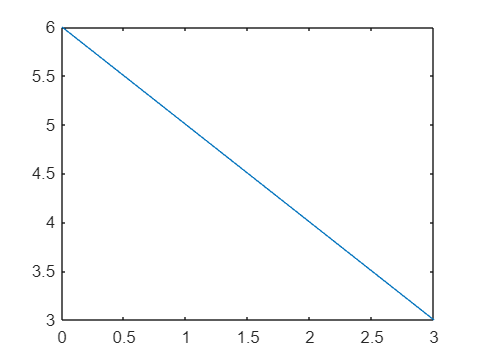

plot(x,y1)

## Task 4

The equation of the second line is y=2+3x.

Task

Create a vector of *y*-values for the second equation using `x` as the input. Name the vector `y2`.

y2=2+3*x

y2 =     2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545    5.5455    5.6364    5.7273    5.8182    5.9091    6.0000    6.0909    6.1818    6.2727    6.3636    6.4545


## Task 5

Use the `hold ``on` command to plot `y2` as a function of `x` on the same figure as `y1`. 

Remember to use the `hold ``off` command when you're finished adding to your plot.

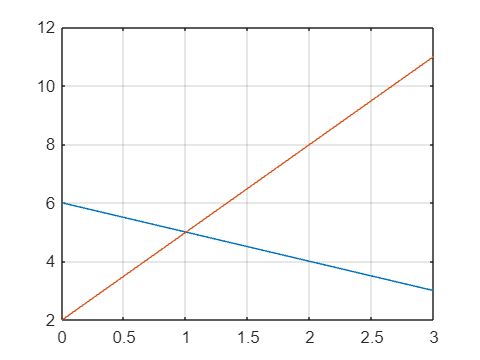

hold on 
plot(x,y2)
hold off
grid on

## Task 6

From the plot, you can identify that the point of intersection is (1,5). You can also solve for the point of intersection by turning the linear  equations into a matrix equation and solving using the backslash  operator.

The system of linear equations is:

y=6−x

y=2+3x

Task

Rearrange the equations by bringing all the variables to the left and the  constants to the right. Arrange the variables in the order x, y.

Create a 2-by-2 matrix containing the coefficients. Name this matrix `A`.

A=[1 1;-3 1]

A =      1     1
    -3     1


## Task 7

The equations should be in the form:

1x+1y=6

−3x+1y=2

Task

Assemble the constants on the right side of the equations into a column vector named `b`.

b=[6 2]'

b =      6
     2


## Task 8

The system of equations has now been rewritten as a single matrix equation:

[1 −3;1 1]∗[x y']=[6 2]'

or more simply:A**x**=**b**

You can now solve for **x** using the backslash operator (`\`).

Task

Solve for **x** using the command `A``\``b`. Assign the output to a variable `point`.

You may want to leave off the semicolon to display the output.

point=A\b

point =     1.0000
    5.0000


## Further Practice

The vector `point` in our Workspace is the point (1,5), which matches the point of intersection found by visually inspecting the plot.

You can verify the solution is correct by plotting `point`. You can accomplish this with the commands

`x = point(1);`

`y = point(2);`

`hold ``on`

`plot(x,y,"ro")`

`hold ``off`

.

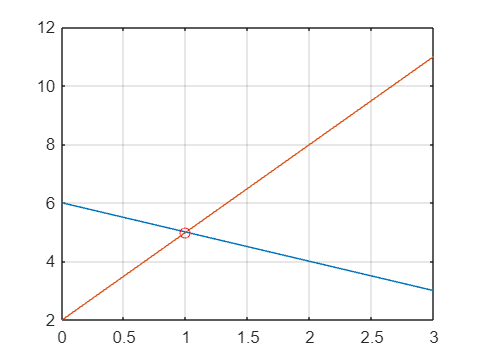

x = point(1);
y = point(2);
hold on
plot(x,y,"ro")
hold off